
clear;
% 参数设置  
Fs = 2e3; % 采样频率  
T = 1/Fs;  % 采样周期  
L = 128;  % 信号长度  
t = (0:L-1)*T; % 时间向量 
delta_f = Fs/L;
f0 = 5e2;
A = sqrt(2);     % 振幅  
phi_0 = 0;   % 相位

%不同频率

n = 1000;%蒙特卡洛实验次数
f = f0-delta_f/2:delta_f/20:f0+delta_f/2;%频率
x = ones(length(f),L);
x_I = 0.5*sin(2*pi*(f0+delta_f)*t + pi/2);
for j = 1:length(f)
    x(j,:) = A*sin(2*pi*f(j)*t + phi_0);
end
temp = x;
window=hann(L);
RMS_Dirc = ones(1,length(f));%RMS值
RMS_Rife= ones(1,length(f));
RMS_Irife = ones(1,length(f));
RMS_AIrife = ones(1,length(f));
RMS_Quinn = ones(1,length(f));
RMS_Quinn_About = ones(1,length(f));

Var_Dirc = ones(1,length(f));%方差
Var_Rife= ones(1,length(f));
Var_Irife = ones(1,length(f));
Var_AIrife = ones(1,length(f));
Var_Quinn = ones(1,length(f));
Var_Quinn_About = ones(1,length(f));

sigma = 1;
for j = 1:length(f)
    x = ones(n,L);
    for k = 1:n
        x(k,:) = temp(j,:) + sigma^2*randn([1,L]);%snr = 0dB
        %x(k,:) = x(k,:) + x_I;%加干扰
        x(k,:) = x(k,:).*window';%加窗
    end
    f_est_Dirc = ones(1,n);
    f_est_Rife = ones(1,n);
    f_est_Irife = ones(1,n);
    f_est_AIrife = ones(1,n);
    f_est_Quinn = ones(1,n);
    f_est_Quinn_About = ones(1,n);
    for m = 1:n    
        f_est_Dirc(m) = Dirc_esti(x(m,:),t);
        f_est_Rife(m) = Rife_esti(x(m,:),t);
        f_est_Irife(m) = Irife_esti(x(m,:),t);       
        f_est_AIrife(m) = AIrife_esti(x(m,:),t); 
        f_est_Quinn(m) = Quinn_esti(x(m,:),t);
        f_est_Quinn_About(m) = Quinn_About_esti(x(m,:),t);       
    end
    RMS_Dirc(1,j) = sqrt(sum(f_est_Dirc.^2)/n);%RMS值
    RMS_Rife(1,j) = sqrt(sum(f_est_Rife.^2)/n);
    RMS_Irife(1,j) = sqrt(sum(f_est_Irife.^2)/n);  
    RMS_AIrife(1,j) = sqrt(sum(f_est_AIrife.^2)/n);  
    RMS_Quinn(1,j) = sqrt(sum(f_est_Quinn.^2)/n);
    RMS_Quinn_About(1,j) = sqrt(sum(f_est_Quinn_About.^2)/n);

    Var_Dirc(1,j) = var(f_est_Dirc);%方差
    Var_Rife(1,j) = var(f_est_Rife);
    Var_Irife(1,j) = var(f_est_Irife);  
    Var_AIrife(1,j) = var(f_est_AIrife);  
    Var_Quinn(1,j) = var(f_est_Quinn);
    Var_Quinn_About(1,j) = var(f_est_Quinn_About);
end

SNR = A^2/(2*sigma^2);
Var_CRLB = 6*Fs^2/(4*pi^2*SNR*L*(L^2-1));

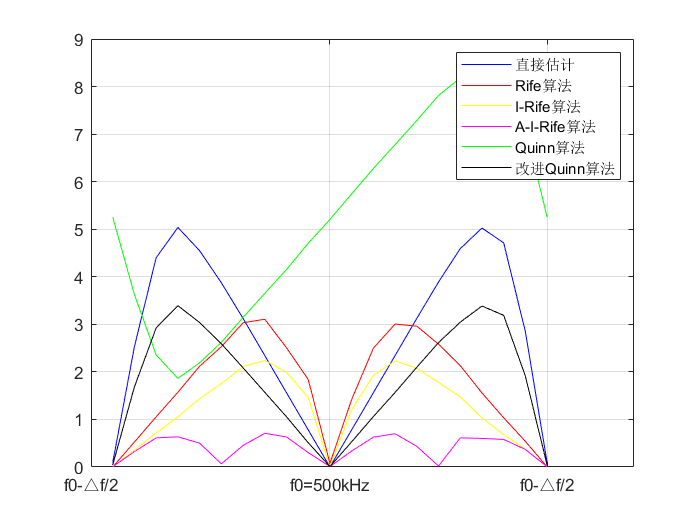

close all;
figure(1);
plot(1:length(f),abs(RMS_Dirc-f),'b');
hold on;
plot(1:length(f),abs(RMS_Rife-f),'r');
hold on;
plot(1:length(f),abs(RMS_Irife-f),'y');
hold on;
plot(1:length(f),abs(RMS_AIrife-f),'m');
hold on;
plot(1:length(f),abs(RMS_Quinn-f),'g');
hold on;
plot(1:length(f),abs(RMS_Quinn_About-f),'k');
xticks([0 11 21]);
xticklabels({'f0-△f/2','f0=500kHz','f0-△f/2'})
legend('直接估计','Rife算法','I-Rife算法','A-I-Rife算法','Quinn算法','改进Quinn算法');  
grid on;

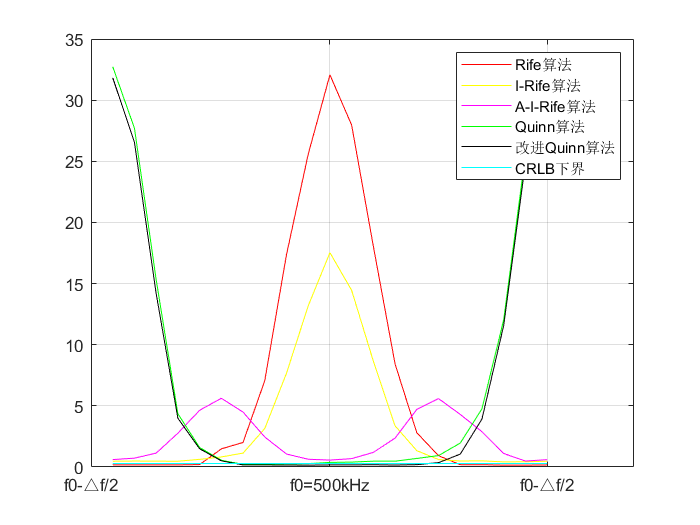

figure(2);
plot(1:length(f),Var_Rife,'r');
hold on;
plot(1:length(f),Var_Irife,'y');
hold on;
plot(1:length(f),Var_AIrife,'m');
hold on;
plot(1:length(f),Var_Quinn,'g');
hold on;
plot(1:length(f),Var_Quinn_About,'k');
hold on;
plot(1:length(f),Var_CRLB*ones(1,length(f)),'c');
xticks([0 11 21]);
xticklabels({'f0-△f/2','f0=500kHz','f0-△f/2'})
legend('Rife算法','I-Rife算法','A-I-Rife算法','Quinn算法','改进Quinn算法','CRLB下界');  
grid on;

%不同信噪比

n = 50000;%蒙特卡洛实验次数
f = f0 + delta_f/3;
x = A*sin(2*pi*f*t + phi_0);
x_I = sin(2*pi*(f+delta_f/2)*t + pi/2);
window=hamming(L);

snr = 0:0.2:10;
sigma = ones(size(snr));
P_signal = 0.5*A^2;
for j = 1:length(snr)
    sigma(j) = sqrt(P_signal*(10^(-snr(j)/10)));
end
temp = x;

RMS_Dirc = ones(1,length(snr));%RMS值
RMS_Rife= ones(1,length(snr));
RMS_Irife = ones(1,length(snr));
RMS_AIrife = ones(1,length(snr));
RMS_Quinn = ones(1,length(snr));
RMS_Quinn_About = ones(1,length(snr));

Var_Dirc = ones(1,length(snr));%方差
Var_Rife= ones(1,length(snr));
Var_Irife = ones(1,length(snr));
Var_AIrife = ones(1,length(snr));
Var_Quinn = ones(1,length(snr));
Var_Quinn_About = ones(1,length(snr));

for j = 1:length(sigma)
    x = ones(n,L);
    for k = 1:n
        a = rand(1);
        x(k,:) = temp + sqrt(2)*sigma(j)^2*x_I + 1*randn([1,L]);%snr = 0dB
    end
    %x(k,:)= x(k,:).*window';%加窗
    f_est_Dirc = ones(1,n);
    f_est_Rife = ones(1,n);
    f_est_Irife = ones(1,n);
    f_est_AIrife = ones(1,n);
    f_est_Quinn = ones(1,n);
    f_est_Quinn_About = ones(1,n);
    for m = 1:n    
        f_est_Dirc(m) = Dirc_esti(x(m,:),t);
        f_est_Rife(m) = Rife_esti(x(m,:),t);
        f_est_Irife(m) = Irife_esti(x(m,:),t);       
        f_est_AIrife(m) = AIrife_esti(x(m,:),t); 
        f_est_Quinn(m) = Quinn_esti(x(m,:),t);
        f_est_Quinn_About(m) = Quinn_About_esti(x(m,:),t);       
    end
    RMS_Dirc(1,j) = sqrt(sum(f_est_Dirc.^2)/n);%RMS值
    RMS_Rife(1,j) = sqrt(sum(f_est_Rife.^2)/n);
    RMS_Irife(1,j) = sqrt(sum(f_est_Irife.^2)/n);  
    RMS_AIrife(1,j) = sqrt(sum(f_est_AIrife.^2)/n);  
    RMS_Quinn(1,j) = sqrt(sum(f_est_Quinn.^2)/n);
    RMS_Quinn_About(1,j) = sqrt(sum(f_est_Quinn_About.^2)/n);

    Var_Dirc(1,j) = var(f_est_Dirc);%方差
    Var_Rife(1,j) = var(f_est_Rife);
    Var_Irife(1,j) = var(f_est_Irife);  
    Var_AIrife(1,j) = var(f_est_AIrife);  
    Var_Quinn(1,j) = var(f_est_Quinn);
    Var_Quinn_About(1,j) = var(f_est_Quinn_About);
end


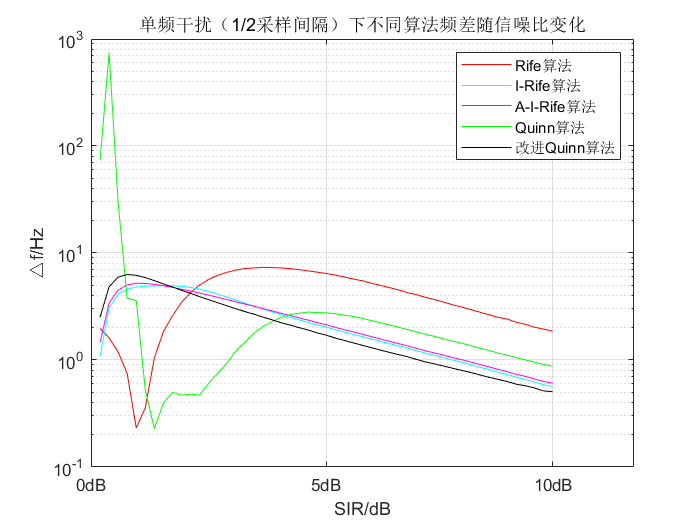

close all;
figure(3);
semilogy(1:length(snr),abs(RMS_Rife-f),'r');
hold on;
semilogy(1:length(snr),abs(RMS_Irife-f),'c');
hold on;
semilogy(1:length(snr),abs(RMS_AIrife-f),'m');
hold on;
semilogy(1:length(snr),abs(RMS_Quinn-f),'g');
hold on;
semilogy(1:length(snr),abs(RMS_Quinn_About-f),'k');
xticks([0 26 51]);
xticklabels({'0dB','5dB','10dB'});
legend('Rife算法','I-Rife算法','A-I-Rife算法','Quinn算法','改进Quinn算法');  
title('单频干扰（1/2采样间隔）下不同算法频差随信噪比变化');
xlabel('SIR/dB')
ylabel('△f/Hz')
grid on;

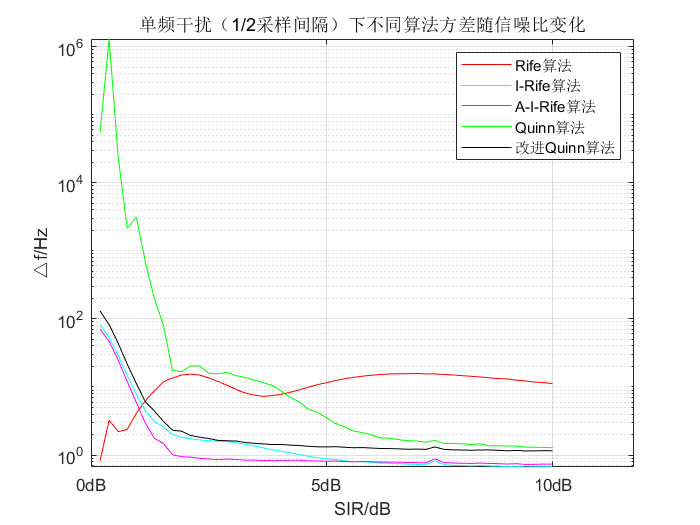

figure(4);
semilogy(1:length(snr),Var_Rife,'r');
hold on;
semilogy(1:length(snr),Var_Irife,'c');
hold on;
semilogy(1:length(snr),Var_AIrife,'m');
hold on;
semilogy(1:length(snr),Var_Quinn,'g');
hold on;
semilogy(1:length(snr),Var_Quinn_About,'k');
xticks([0 26 51]);
xticklabels({'0dB','5dB','10dB'});
legend('Rife算法','I-Rife算法','A-I-Rife算法','Quinn算法','改进Quinn算法');  
title('单频干扰（1/2采样间隔）下不同算法方差随信噪比变化');
xlabel('SIR/dB')
ylabel('△f/Hz')
grid on;